# Numerical Definite Integration


$$\int_a^b{f\left( x \right) dx}$$


- integral function: $f\left( x \right)$

- upper limit: $b$

- lower limit: $a$

- number of splited intervals: $h,N;\,x_0,x_1,...,x_N;\,\,f_0,f_1,...,f_N
$

## function

mathematics: a process mapping element in set X to element in set Y (see wiki)

MATLAB: 

- function ret = function_name()

- hf1 = @(x) 3*x.^3

hf1 = @(x) 3*x.^3.*sin(x); %doc('@'); doc('function handle');
disp(hf1(1.2))

    4.8317


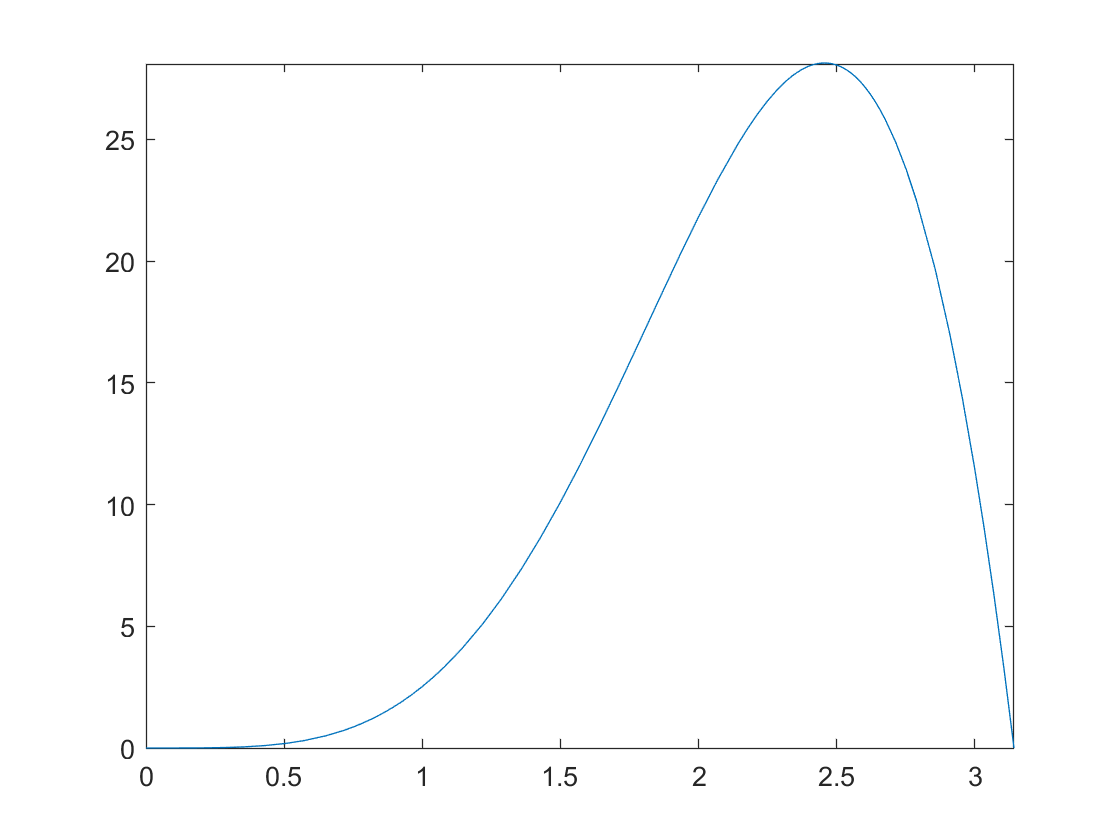

fplot(hf1, [0,pi])

## paramter

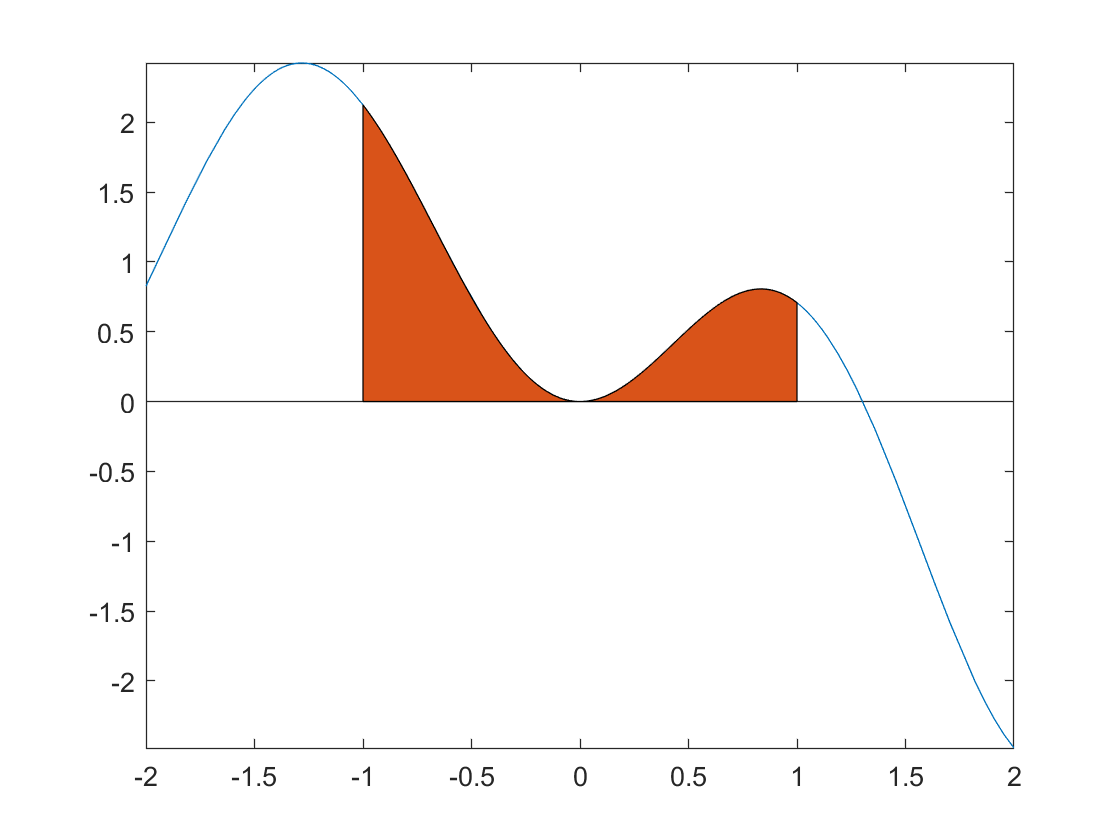

hf1 = @(x) (3-x-x.^2).*sin(x).^2; %integral function; hf short for function handle
a = -1; %lower limit
b = 1; %upper limit

% plot integral area
figure()
fplot(hf1, [a-1,b+1])
hold on;
area(linspace(a,b), hf1(linspace(a,b)))
hold off

## built-in (always check built-in first)

ret1 = integral(hf1, a, b); %doc('integral')
disp(['built-in integral: ', num2str(ret1,14)])

built-in integral: 1.321971464861


## rectangular rule

wiki - Riemann sum / Methods / Midpoint rule: [https://en.wikipedia.org/wiki/Riemann_sum](https://en.wikipedia.org/wiki/Riemann_sum)

error analysis (see lecture note): $\frac{f''\left( \xi \right) \left( b-a \right) ^3}{24N^2}$

ret1 = my_rectangular_integral(hf1, a, b, 100);
disp(['my_rectangular_integral: ', num2str(ret1,14)])

my_rectangular_integral: 1.3219580469182


## trapezoidal rule

wiki - trapezoidal rule: [https://en.wikipedia.org/wiki/Trapezoidal_rule](https://en.wikipedia.org/wiki/Trapezoidal_rule)

error analysis (see wiki): $\frac{f''\left( \xi \right) \left( b-a \right) ^3}{12N^2}$

ret1 = my_trapezoidal_integral(hf1, a, b, 100);
disp(['my_trapezoidal_integral: ', num2str(ret1,14)])

my_trapezoidal_integral: 0


## Simpsom's rule

wiki - Simpsom's rule: [https://en.wikipedia.org/wiki/Simpson%27s_rule](https://en.wikipedia.org/wiki/Simpson%27s_rule)

ret1 = my_Simpsom_integral(hf1, a, b, 8); % 8 is number of adaptive iteration
disp(['my_Simpsom_integral: ', num2str(ret1,14)])

my_Simpsom_integral: 0


## Monte Carlo's rule

wiki - Mote Carlo Integration: [https://en.wikipedia.org/wiki/Monte_Carlo_integration](https://en.wikipedia.org/wiki/Monte_Carlo_integration)

ret1 = my_MonteCarlo_rule(hf1, a, b, 5000); % 5000 is number of random generated point
disp(['my_MonteCarlo_rule: ', num2str(ret1,14)])

my_MonteCarlo_rule: 1.3223980466521


## function

function ret = my_rectangular_integral(hf1, a, b, num_point)
tmp1 = linspace(a,b,num_point+1);
x = (tmp1(1:(end-1))+tmp1(2:end))/2;
ret = sum(hf1(x))*(b-a)/num_point;
end

function ret = my_trapezoidal_integral(hf1, a, b, num_point)
ret = 0;
% not available util 20181004
end

function ret = my_Simpsom_integral(hf1, a, b, num_iter)
ret = 0;
% not available util 20181004
end

function ret = my_MonteCarlo_rule(hf1, a, b, num_point)
x = rand([1,num_point])*(b-a) + a;
ret = sum(hf1(x))/num_point * (b-a);
end
